clc;
clear;
addpath(genpath('Pendulum'),genpath('Control_Bootcamp'));

M = .5;
m = .2;
b = .1;
L = .3;
I = .006;
g = 9.8;

P = (M+m)*I+M*m*L^2;

## 构建系统状态方程

% 取θ=π为系统平衡点

A = [0 1 0 0;
     0 -(I+m*L^2)*b/P (m^2*g*L^2)/P 0;
     0 0 0 1;
     0 -(m*L*b)/P (m*g*L*(M+m))/P 0];
B = [0;
     (I+m*L^2)/P;
     0;
     (m*L)/P];

C = [1 0 0 0;
     0 0 1 0];

D = [0;
     0];

states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'u'};
outputs = {'x';'phi'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

sys_ss =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot          0  -0.1818    2.673        0
   phi            0        0        0        1
   phi_dot        0  -0.4545    31.18        0
 
  B = 
                u
   x            0
   x_dot    1.818
   phi          0
   phi_dot  4.545
 
  C = 
              x    x_dot      phi  phi_dot
   x          1        0        0        0
   phi        0        0        1        0
 
  D = 
        u
   x    0
   phi  0
 
连续时间状态空间模型。



[num , den] = tfdata(sys_ss)

num = 2×1 cell 数组
    {[0 0 1.8182 4.8446e-15 -44.5455]}
    {[        0 0 4.5455 -8.1528e-16]}


den = 2×1 cell 数组
    {[1 0.1818 -31.1818 -4.4545 0]}
    {[  1 0.1818 -31.1818 -4.4545]}


sys_tf1 = tf(num,den)

sys_tf1 =
 
  从输入到输出...
          1.818 s^2 + 4.845e-15 s - 44.55
   1:  --------------------------------------
       s^4 + 0.1818 s^3 - 31.18 s^2 - 4.455 s
 
              4.545 s - 8.153e-16
   2:  ----------------------------------
       s^3 + 0.1818 s^2 - 31.18 s - 4.455
 
连续时间传递函数。
模型属性


sys_tf = tf(sys_ss)

sys_tf =
 
  从输入 "u" 到输出...
          1.818 s^2 + 4.845e-15 s - 44.55
   x:  --------------------------------------
       s^4 + 0.1818 s^3 - 31.18 s^2 - 4.455 s
 
                4.545 s - 8.153e-16
   phi:  ----------------------------------
         s^3 + 0.1818 s^2 - 31.18 s - 4.455
 
连续时间传递函数。
模型属性


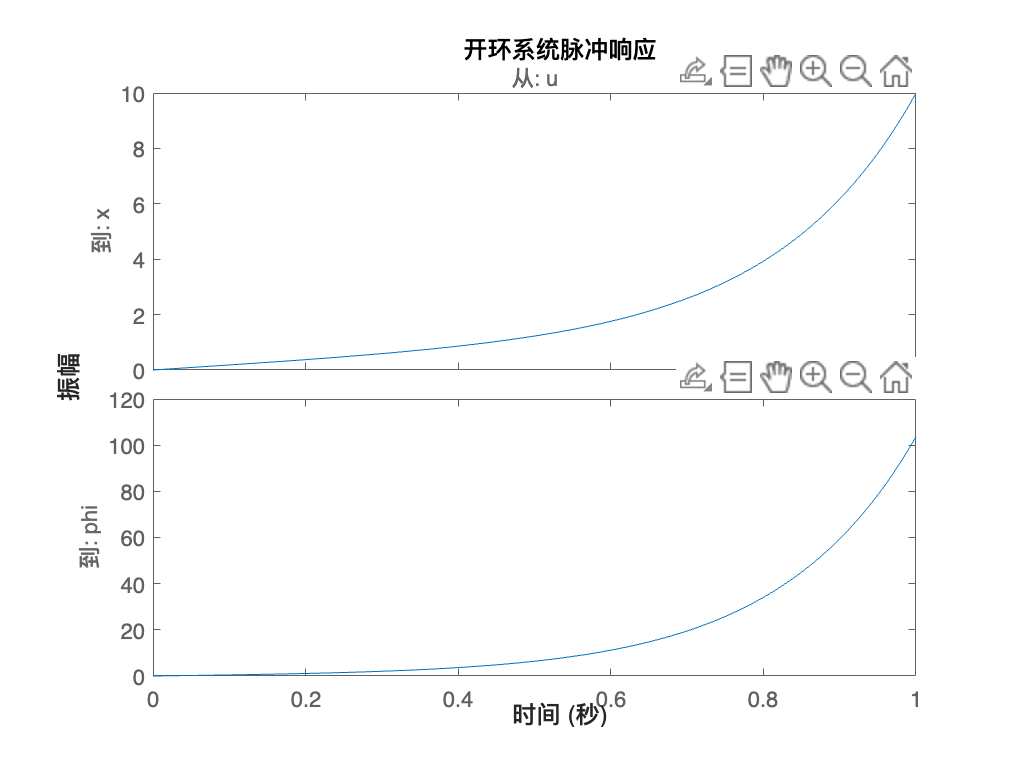


t = 0:0.01:1;
impulse(sys_ss,t);
title('开环系统脉冲响应')

% 脉冲响应表现为推车无限向右移动 且仅对小角度有效果


% 判别系统稳定性
lambda = eig(A)

lambda =          0
   -0.1428
   -5.6041
    5.5651


% 最后一项为正数 开环系统不稳定

% 判别系统可控性
Ctrb = ctrb(A,B)

Ctrb =          0    1.8182   -0.3306   12.2089
    1.8182   -0.3306   12.2089   -4.4287
         0    4.5455   -0.8264  141.8858
    4.5455   -0.8264  141.8858  -31.3196



[c,r] = size(Ctrb)

c = 4

r = 4

if rank(Ctrb) == min(c,r)
    disp('系统可控');
else
    disp('系统不可控');
end

系统可控



% 极点配置法 改变特征值 使系统稳定
eigs = [-1.1;-1.2;-1.3;-1.4];
K = place(A,B,eigs)

K =    -0.0539   -0.2740    8.9386    1.1696


eig(A-B*K)

ans =    -1.4000
   -1.3000
   -1.2000
   -1.1000
